%% Opgave 1

%%%%%%%%%%%%%%%%%%%%%%
% 1. find værdi af k %
%%%%%%%%%%%%%%%%%%%%%%

% for at fx(x) er en gyldig tæthedsfunktion skal summen af de mulige udfald
% være lig 1.

% summen af sandsynlighederne lig 1: k+k+k+k+k+k+k=1
% k er derfor lig = 1/7

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2. skitser tæthedsfuntkion %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

k = 1/7;

x = [-3, 0, 2, 4, 7, 10, 12]

x =     -3     0     2     4     7    10    12


y = [k, k, k, k, k, k, k, ]

y =     0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429


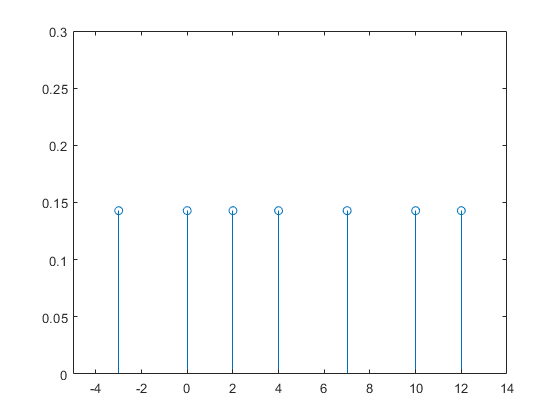


stem(x, y);
xlim([-5 14]);
ylim([0, 0.30]);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3. bestem forventningsværdien og variansen af X udfra fx(x) %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% forventningsværdien findes ved at gange sansynligheden på hver af de 7
% udfald og ligge dem sammen
% E[x] = summen af x*fx(x) = 
% fv = 1/7*-3 + 1/7*0 + 1/7*2 + 1/7*4 + 1/7*7 + 1/7*10 + 1/7*12 =
% fv = 1/7(-3 + 0 + 2 + 4 + 7 + 10 + 12)

fv = 1/7 * (-3 + 0 + 2 + 4 + 7 + 10 + 12)

fv = 4.5714


% den forventede værdi vil derfor være 4.5714

% variansen findes ved at bruge formlen E[x^2] - E[x]^2
% E[x] er allerede fundet ovenfor ved forventningsværdien så: E[x] = 4.5714

% E[x^2] = x^2*fx(x) =
% var = 1/7*-3^2 + 1/7*0^2 + 1/7*2^2 + 1/7*4^2 + 1/7*7^2 + 1/7*10^2 + 1/7*12^2
% var = 1/7(-3^2 + 0^2 + 2^2 + 4^2 + 7^2 + 10^2 + 12^2)
ex2 = 1/7 * ((-3)^2 + 0^2 + 2^2 + 4^2 + 7^2 + 10^2 + 12^2)

ex2 = 46


% da vi nu har både E[x] og E[x^2] kan vi blot bruge formlen for varians: 
% E[x] = 4.5714
% E[x^2] = 46

% var(x) = E[x^2] - E[x]^2
var = 46 - 4.5714^2

var = 25.1023


% variansen er derfor 25.1023

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4. beregn sandsynlighed for x=>2 og x>2 %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% sandsynligheden for at få en x større end eller lig med 2 er lig med summen af alle
% sandsynligheder lig med eller over 2, altså summen af sandsynlighederne
% for 2, 4, 7, 10 og 12

% pr2 = Pr(2) + Pr(4) + Pr(7) + Pr(10) + Pr(12)
pr2 = 1/7 + 1/7 + 1/7 + 1/7 + 1/7

pr2 = 0.7143


% sansynliheden for at få en værdi større end eller lig med 2 er derfor
% 0.7143 ~ 5/7

% sandsynligheden for at få en værdi større end 2 således summen af
% sandsynligheden for alle værdi over 2, altså 4, 7, 10, 12
% 

% pr22 = Pr(4) + Pr(7) + Pr(10) + Pr(12)
pr22 = 1/7 + 1/7 + 1/7 + 1/7

pr22 = 0.5714

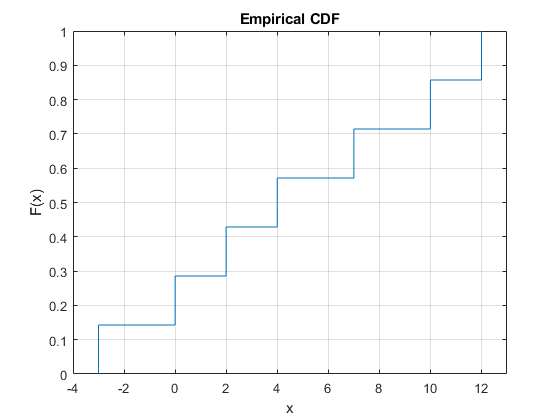


% sanddsynligheden for at få en værdi større end 2 er derfor 0.5714 ~ 4/7

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 5. bestem fordelingsfunktionen (cdf) for x %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% fordelingsfunktionen er sandsynloigheden for alle værdier opsummeret.
% for at finde fordelingsfunktionen tager man sandsynligheden for at x er
% mindre end eller lig med et udfald, f.eks. fx(0) = fx(-3) + fx(0)
% derved er fordelingsfunktionen: 
% Fx(x) = 0   x < 3
%       = 1/7   x < 3
%       = 2/7   x <= 0
%       = 3/7   x <= 2
%       = 4/7   x <= 4
%       = 5/7   x <= 7
%       = 6/7   x <= 10
%       = 7/7   x <= 12

% derved danner fordelingsfunktoinen en trappe, som angiver sandsynligheden
% for at få en af de udfald der ligger under. Dette graf er skitseret
% nedenfor.

cdfplot(x)
xlim([-4, 13])